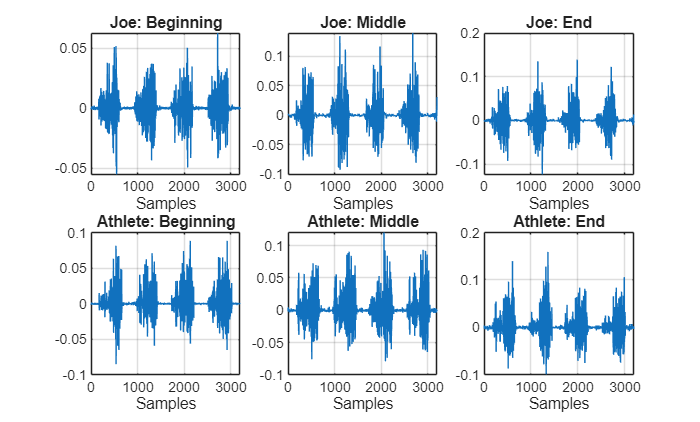


% Lab Task 2: Estimating fatigue in EMG

% Load the data
load('emg_data.mat');

% Define sampling frequency 
fs = 1000; 

% Part 1: Plotting the raw EMG segments
figure('Name', 'Raw EMG Segments');

% Regular Joe
subplot(2,3,1); plot(emg_regular_joe.Beginning); title('Joe: Beginning'); xlabel('Samples');
grid on;
subplot(2,3,2); plot(emg_regular_joe.Middle); title('Joe: Middle'); xlabel('Samples');
grid on;
subplot(2,3,3); plot(emg_regular_joe.End); title('Joe: End'); xlabel('Samples');
grid on;
% Athlete
subplot(2,3,4); plot(emg_athlete.Beginning); title('Athlete: Beginning'); xlabel('Samples');
grid on;
subplot(2,3,5); plot(emg_athlete.Middle); title('Athlete: Middle'); xlabel('Samples');
grid on;
subplot(2,3,6); plot(emg_athlete.End); title('Athlete: End'); xlabel('Samples');
grid on;

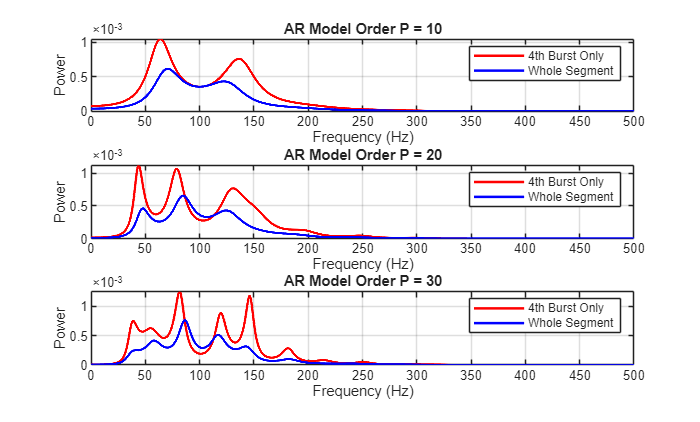


% Part 2: Isolated Burst vs. Whole Segment Analysis
% Extract the 4th burst from Regular Joe's Beginning segment

idx_start = 2500; 
idx_end = 3000;  
burst4 = emg_regular_joe.Beginning(idx_start:idx_end);
whole_segment = emg_regular_joe.Beginning;

figure('Name', 'AR Spectra: Burst vs Whole Segment');
P_values = [10, 20, 30];

for i = 1:length(P_values)
    P = P_values(i);
    
    % Use the provided function ([Phi, f] = myARspectrum(x, P, fs))
    [Phi_burst, f_grid] = my_AR_spectrum(burst4, P, fs);
    [Phi_whole, ~] = my_AR_spectrum(whole_segment, P, fs);
    
    subplot(3, 1, i);
    plot(f_grid, Phi_burst, 'r', 'LineWidth', 1.5); hold on;
    plot(f_grid, Phi_whole, 'b', 'LineWidth', 1.5);
    title(['AR Model Order P = ', num2str(P)]);
    legend('4th Burst Only', 'Whole Segment');
    xlabel('Frequency (Hz)'); ylabel('Power');
    grid on;
end

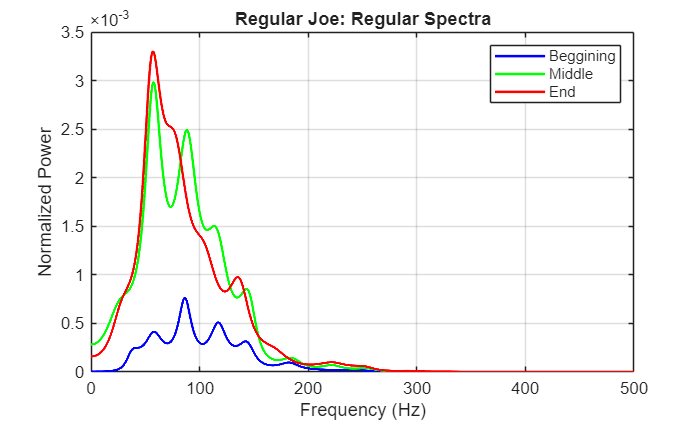



% Parts 3 & 4: Regular Joe - Normalized Spectra and Mean Frequency
segments_joe = {emg_regular_joe.Beginning, emg_regular_joe.Middle, emg_regular_joe.End};
labels = {'Beginning', 'Middle', 'End'};
colors = {'b', 'g', 'r'};
figure('Name', 'Regular Joe: Spectra');

%Estimate regular spectra P=30
for i=1:length(segments_joe)

     % Estimate spectrum with P=30
    [Phi, f_grid] = my_AR_spectrum(segments_joe{i}, 30, fs);

    Phi = Phi(:); 
    f_grid = f_grid(:);
    
    plot(f_grid, Phi, colors{i}, 'LineWidth', 1.5); hold on;
end

title('Regular Joe: Regular Spectra');
legend ('Beggining','Middle','End');
xlabel('Frequency (Hz)'); ylabel('Normalized Power');
grid on;

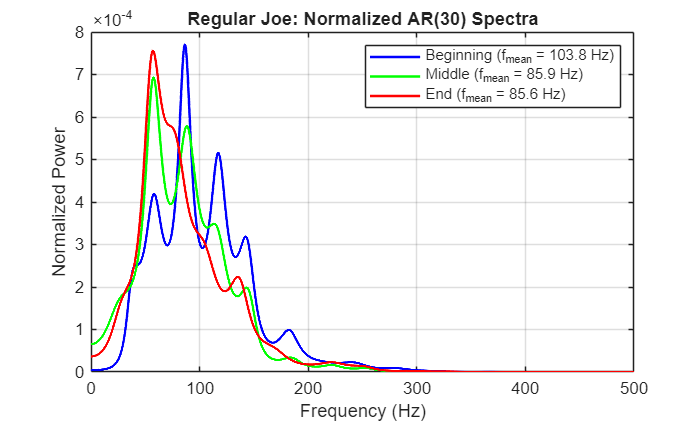



figure('Name', 'Regular Joe: Normalized Spectra');
fmean_joe = zeros(1, 3);

for i = 1:3
    % Estimate spectrum with P=30
    [Phi, f_grid] = my_AR_spectrum(segments_joe{i}, 30, fs);
    
    Phi = Phi(:); 
    f_grid = f_grid(:);
    
    % Normalize the spectrum
    Phi_norm = Phi / sum(Phi);
    
     % Plot normalized spectrum
    plot(f_grid, Phi_norm, colors{i}, 'LineWidth', 1.5); hold on;
    
    % Compute mean frequency (center of mass)
    fmean_joe(i) = f_grid' * Phi_norm; 
end

title('Regular Joe: Normalized AR(30) Spectra');
legend(['Beginning (f_{mean} = ', num2str(fmean_joe(1), '%.1f'), ' Hz)'], ...
       ['Middle (f_{mean} = ', num2str(fmean_joe(2), '%.1f'), ' Hz)'], ...
       ['End (f_{mean} = ', num2str(fmean_joe(3), '%.1f'), ' Hz)']);
xlabel('Frequency (Hz)'); ylabel('Normalized Power');
grid on;

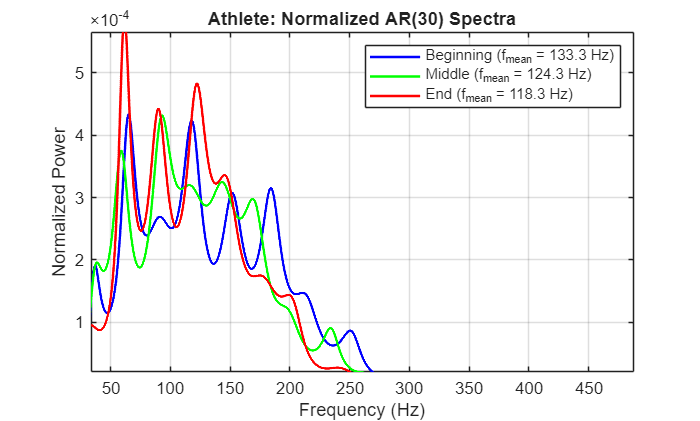



%% Part 5: Athlete - Normalized Spectra and Mean Frequency
segments_athlete = {emg_athlete.Beginning, emg_athlete.Middle, emg_athlete.End};

figure('Name', 'Athlete: Normalized Spectra');
fmean_athlete = zeros(1, 3);

for i = 1:3
    [Phi, f_grid] = my_AR_spectrum(segments_athlete{i}, 30, fs);
    
    Phi = Phi(:); f_grid = f_grid(:);
    Phi_norm = Phi / sum(Phi);
    
    plot(f_grid, Phi_norm, colors{i}, 'LineWidth', 1.5); hold on;
    
    fmean_athlete(i) = f_grid' * Phi_norm;
end

title('Athlete: Normalized AR(30) Spectra');
legend(['Beginning (f_{mean} = ', num2str(fmean_athlete(1), '%.1f'), ' Hz)'], ...
       ['Middle (f_{mean} = ', num2str(fmean_athlete(2), '%.1f'), ' Hz)'], ...
       ['End (f_{mean} = ', num2str(fmean_athlete(3), '%.1f'), ' Hz)']);
xlabel('Frequency (Hz)'); ylabel('Normalized Power');
grid on;